This Matlab code is used for demonstration of the clustering results of DP, LC-DP and DC-HDP. 

For details, please refer to the Information Systems paper: Hierarchical clustering that takes advantage of both density-peak and density-connectivity

Written by Ye Zhu, Deakin University, April 2021, version 1.0. This software is under GNU General Public License version 3.0 (GPLv3).

clear

load('2O.mat')
 
data = normalize(data); % Min-Max normalisation 

DisMatrix = pdist2(data,data,'minkowski',2); % calculate pairwise distance


# Original DP clustering

Obtaining the clustering results of original DP clustering algorithm

eps=0.05; % density estimator bandwidth

Z = OHierDP(DisMatrix,eps);  % Obtaining the hierarchy of clusters identified by DP

%%%% if you are only interested in the clustering labels, just run the following two lines 

k=2; % identify 2 clusters 
Tclass = cluster(Z,'maxclust',k); % Tclass is the hierarchical clustering result  
 
%%%% Evaluate clustering result

f1 = fmeasure(class, Tclass);
disp(strcat("F1 score of DP clustering: ", num2str(f1)));

F1 score of DP clustering: 0.55999


Visualisation the clustering results of original DP in a hierarchical structure

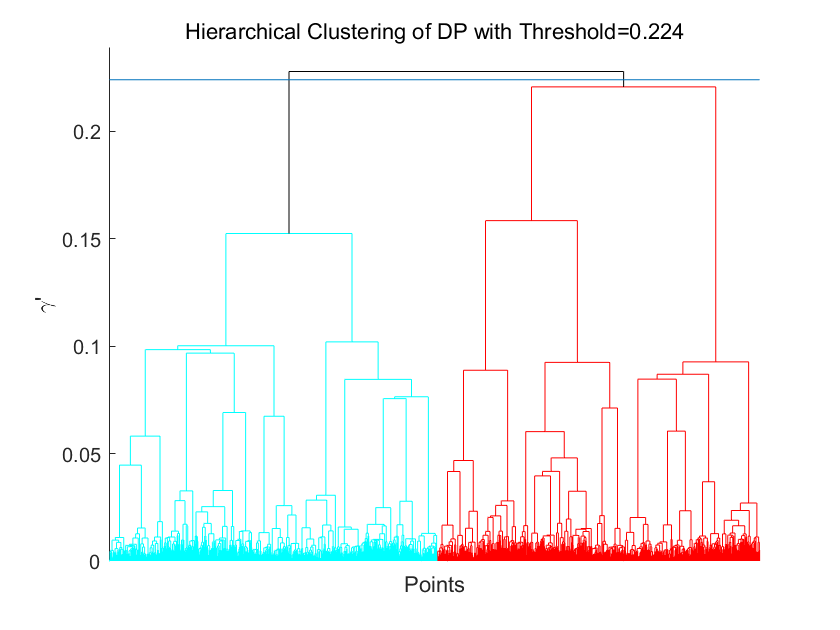

t=0.224; % height threshold for hierarchical clustering

figure
[H,T]= dendrogram(Z,size(data,1),'Orientation','top','ColorThreshold',t);


xticks([])
xlabel('Points')
ylabel('\gamma''')


hold on
line([1,size(data,1)],[t,t])
title(['Hierarchical Clustering of DP with Threshold=' num2str(t)])


lineColours = cell2mat(get(H,'Color'));
colourList = flipud(unique(lineColours, 'rows'));

set(gcf,'color','w');


Visualising the clustering result of original DP with a scatter plot

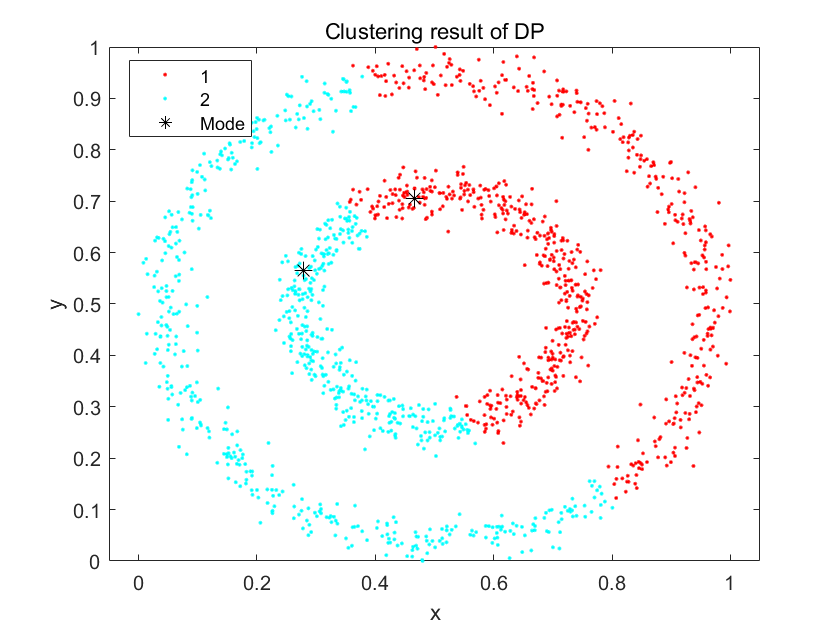

Col=[];
Tclass=[]; % find the line color accociated with cluster labels
for i=1:length(data)
    [a,~]=find(Z==i);
    Col(i,:)=lineColours(a,:);
    [~,b] = ismember(lineColours(a,:),colourList,'rows');
    Tclass(i)=b;   
end 

 
if sum(Tclass<0)>0
   colourList= [[0.8 0.8 0.8];colourList];
end
 
figure
x = data(:,1); y = data(:,2);
gscatter(x,y,Tclass,colourList);

[centre] = cluCentre( data,Tclass,eps);  % identify cluster centres/modes
hold on
a=scatter(centre(:,1),centre(:,2),70,'k','*');
lgd = legend('show');
lgd.String{end}='Mode';
title(['Clustering result of DP'])

# LC-DP clustering

Obtaining the clustering results of LC-DP clustering algorithm

eps=0.05; % density estimator bandwidth
Kn=10; % k

Density=sum(DisMatrix'<=eps)';
[LC] = getLC(DisMatrix,Density,Kn);
Z = LCHierDP(DisMatrix,LC'); % Obtaining the hierarchy of clusters identified by LC-DP

%%%% if you are only interested in the clustering labels, just run the following two lines 

k=2; % identify 2 clusters 
Tclass = cluster(Z,'maxclust',k); % Tclass is the hierarchical clustering result   

%%%% Evaluate clustering result

f1 = fmeasure(class, Tclass);
disp(strcat("F1 score of LC-DP clustering: ", num2str(f1)));

F1 score of LC-DP clustering: 0.56333


Visualisation the clustering results of LC-DP in a hierarchical structure

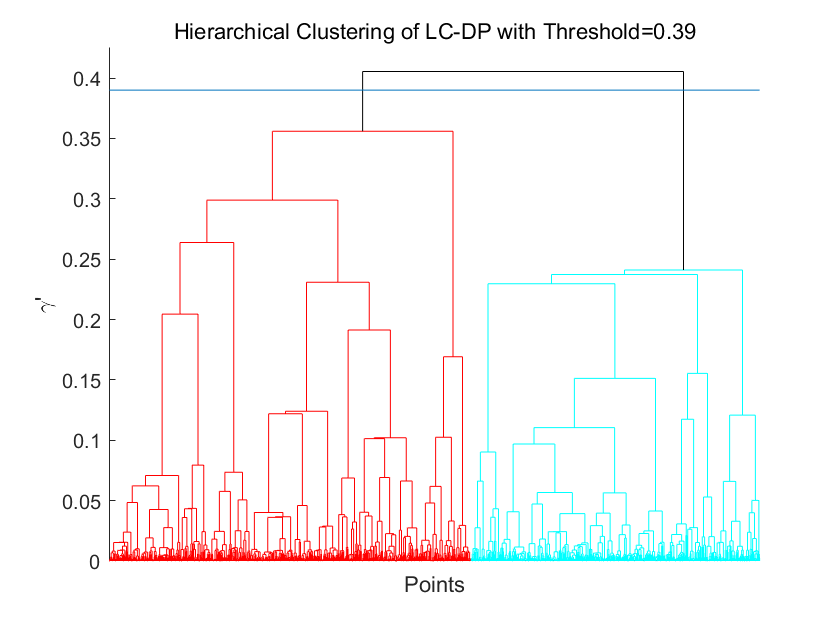

t=0.39; % height threshold for hierarchical clustering

figure
[H,T]= dendrogram(Z,size(data,1),'Orientation','top','ColorThreshold',t);


xticks([])
xlabel('Points')
ylabel('\gamma''')


hold on
line([1,size(data,1)],[t,t])
title(['Hierarchical Clustering of LC-DP with Threshold=' num2str(t)])


lineColours = cell2mat(get(H,'Color'));
colourList = flipud(unique(lineColours, 'rows'));

set(gcf,'color','w');


Visualising the clustering result of LC-DP with a scatter plot

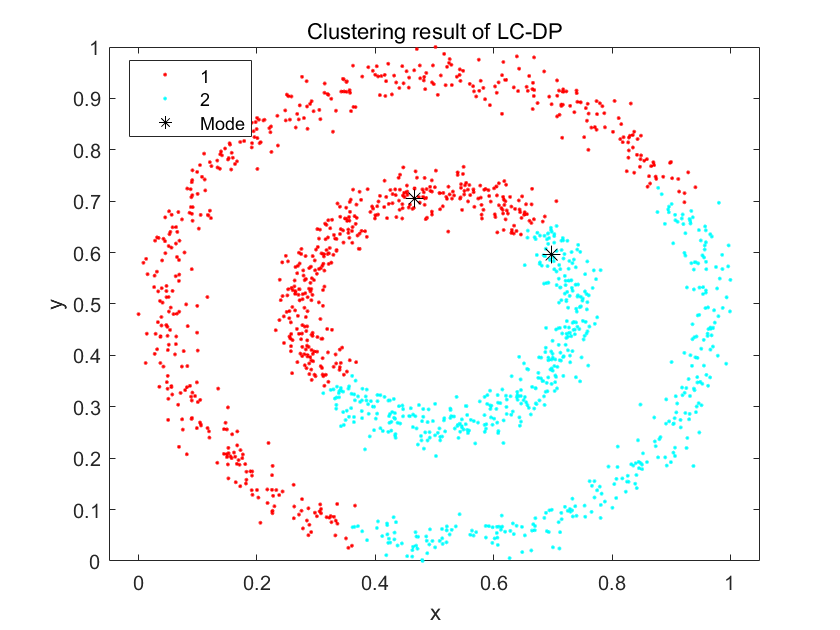

Col=[];
Tclass=[]; % find the line color accociated with cluster labels
for i=1:length(data)
    [a,~]=find(Z==i);
    Col(i,:)=lineColours(a,:);
    [~,b] = ismember(lineColours(a,:),colourList,'rows');
    Tclass(i)=b;   
end 

 
if sum(Tclass<0)>0
   colourList= [[0.8 0.8 0.8];colourList];
end
 
figure
x = data(:,1); y = data(:,2);
gscatter(x,y,Tclass,colourList);

[centre] = cluCentre( data,Tclass,eps);  % identify cluster centres/modes
hold on
a=scatter(centre(:,1),centre(:,2),70,'k','*');
lgd = legend('show');
lgd.String{end}='Mode';
title(['Clustering result of LC-DP'])

# DC-HDP clustering

Obtaining the clustering results of DC-HDP clustering algorithm

eps=0.05; % density estimator bandwidth
MinPts=1; % density threshold 

Dclass = DBSCAN(DisMatrix,eps,MinPts); % using DBSCAN to check density-connectivity, Dclass is DBSCAN clustering results, "-1" indicates noise points

I = find(Dclass>0);
Z = DCHDP(DisMatrix(I,I),eps,Dclass(I)); % Obtaining the hierarchy of clusters identified by DC-HDP

%%%% if you are only interested in the clustering labels, just run the following three lines 

k=2; % identify 2 clusters 
Tclass = cluster(Z,'maxclust',k); % Tclass is the hierarchical clustering result of non-noisy instances
Dclass(I)= Tclass; % Updating the final clustering labels

%%%% Evaluate clustering result

f1 = fmeasure(class, Dclass);
disp(strcat("F1 score of DC-HDP clustering: ", num2str(f1)));

F1 score of DC-HDP clustering: 1


Visualisation the clustering results of DC-HDP in a hierarchical structure

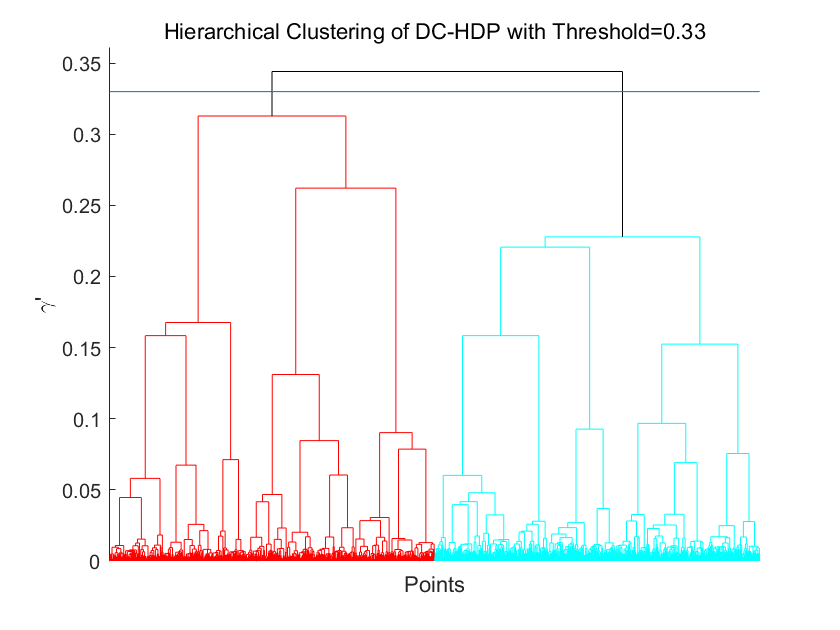

t=0.33; % height threshold for hierarchical clustering

figure
[H,T]= dendrogram(Z,size(data,1),'Orientation','top','ColorThreshold',t);

xticks([])
xlabel('Points')
ylabel('\gamma''')

hold on
line([1,size(data,1)],[t,t])
title(['Hierarchical Clustering of DC-HDP with Threshold=' num2str(t)])


lineColours = cell2mat(get(H,'Color'));
colourList = flipud(unique(lineColours, 'rows'));

set(gcf,'color','w');


Visualising the clustering result of DC-HDP with a scatter plot

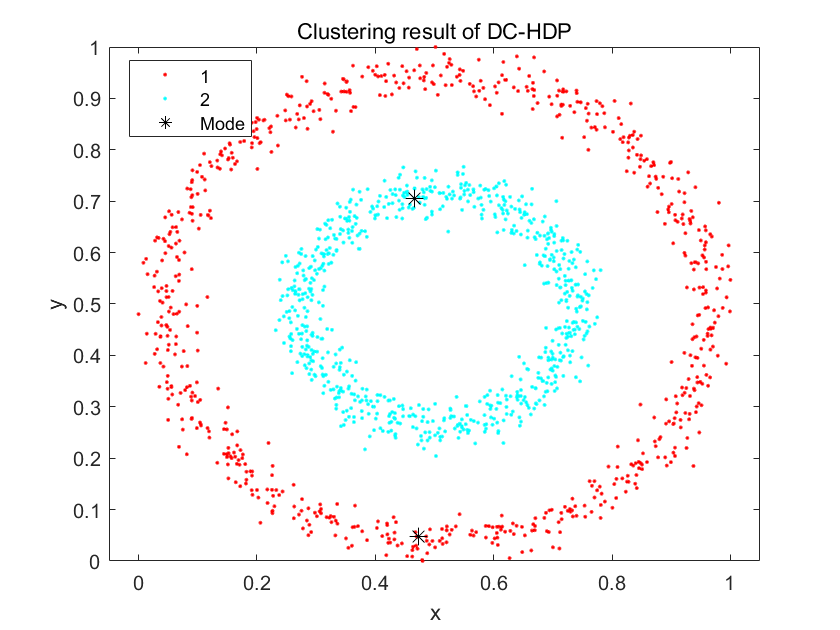

Col=[];
Tclass=[];  % find the line color accociated with cluster labels
for i=1:length(I)
    [a,~]=find(Z==i);
    Col(i,:)=lineColours(a,:);
    [~,b] = ismember(lineColours(a,:),colourList,'rows');
    Tclass(i)=b;
end 
Dclass(I)= Tclass;

if sum(Dclass<0)>0
    colourList= [[0.8 0.8 0.8];colourList];
end

figure
x = data(:,1); y = data(:,2); 
gscatter(x,y,Dclass,colourList);

[centre] = cluCentre( data(I,:),Dclass(I),eps); % identify cluster centres/modes
hold on
a=scatter(centre(:,1),centre(:,2),70,'k','*');
lgd = legend('show');
lgd.String{end}='Mode';
title(['Clustering result of DC-HDP'])